load ('results.mat', 'svm_info', 'y_test');
svm_info

svm_info = struct with fields:
    n_train: [300 500 700 1000 2000 5000]
        acc: [87.5600 91.2400 93.1500 94.0900 95.7700 97.0400]
      y_hat: [10000×6 double]


size(y_test)

ans =        10000           1


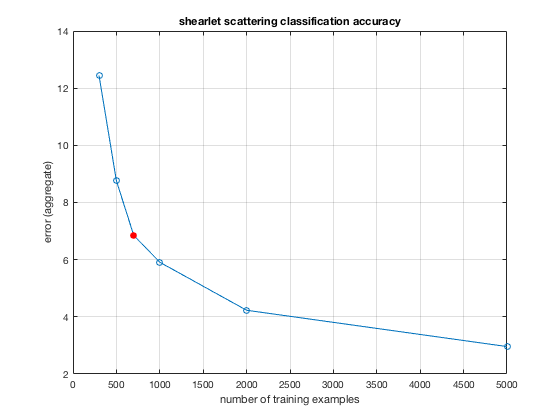

plot(svm_info.n_train, 100-svm_info.acc, '-o')
grid on;
xlabel('number of training examples'); ylabel('error (aggregate)')
title('shearlet scattering classification accuracy')

idx = 3;
hold on; plot(svm_info.n_train(idx), 100 - svm_info.acc(idx), 'ro', 'MarkerFaceColor','r');

C = confusionmat(y_test, svm_info.y_hat(:,idx))

C =          963           0           3           0           0           0          10           1           2           1
           0        1123           3           0           0           1           2           4           2           0
          11          10         959          16           3           2           3           9          17           2
           1           1          18         892           0          64           1          12          14           7
           1           1           1           0         905           1          19           2           1          51
           3           3           2          11           0         851           7           4           7           4
           9           3          12           0          11          15         906           0           2           0
           0          10          22           5           4           0           0         943           8          36
          21           3    


err = 100 * (1-sum(diag(C)) / sum(C(:))) % should agree with plot above

err = 6.8500


sum(C,2)'

ans =          980        1135        1032        1010         982         892         958        1028         974        1009


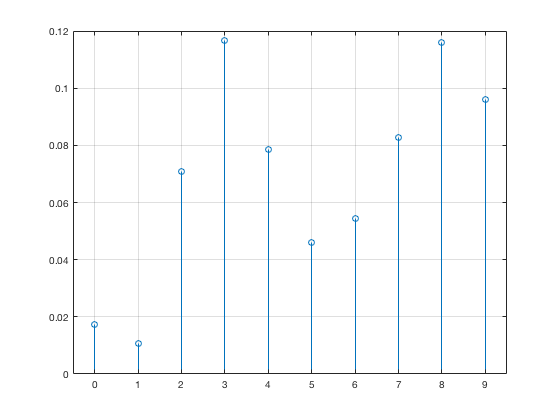

acc_perclass = (sum(C,2) - diag(C)) ./ sum(C,2);
figure; stem(acc_perclass)
xlim([.5, 10.5]);
set(gca, 'XTick', 1:10, 'XTickLabels', 0:9); grid on;